# 離散確率変数

***Author****: Ward Nickle, Humboldt State University*

## 確率分布（Probability Distributions）

確率分布は、確率変数のあらゆる可能な値とその尤度を記述した値の表です。もちろん、これらの表はしばしばグラフでも表現されます。確率分布は相対度数分布と非常によく似ており、試行が十分に繰り返されると、経験的確率が理論的確率に近づいていきます。つまり、サンプルサイズが十分に大きい相対度数分布は、確率分布と考えることができます。

離散的な確率変数とその確率分布を考える際、コインやサイコロ、トランプなどがよく使われます。例えば，コインを2回投げて表が出る数を考える場合，可能なケースは決まっており，それぞれの確率も決まっています。2回のコイン投げでは、表が0回、1回、2回のいずれかしかありません。その結果は次のようになります。

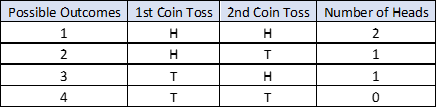 

ここで、確率変数である「表の数」の各値に関連する確率を考えてみると、次のような相対的な頻度で発生していることがわかります。これが確率です。

つまり，4つの可能な結果のうち，「表がでない」または「2回とも表である」という結果は1通りしかなく，「表が1回でる」という結果は2通りしかないということです。これら表の出る数を、可能性のある結果の総数と比較すると、各特定の結果の確率P(x)を示します。確率変数の値は、お互いに排他的であり、重複がなく潜在的に起こり得る値を集合的に網羅しています。したがって、すべての可能な結果が考慮されているという意味で、確率は常に1、つまり100%にならなければなりません。

## 統計量（Statistics）

離散的な確率変数の記述統計量は、加重平均を求めるのに似た方法で求められます。xの確率P(x)は、基本的に各xの重みであり、確率の和が1であることから、平均値は次の式で求められます。


$$\mu =\sum_{i=1}^n \left(x_i P\left(x_i \right)\right)$$
 

分散とその平方根である標準偏差も同様の方法で求められます。

 
$$\sigma^2 =\sum_{i=1}^n \left\lbrack {\left(x_i -\mu \right)}^2 P\left(x_i \right)\right\rbrack$$
            
$$\sigma =\sqrt{\sum_{i=1}^n \left\lbrack {\left(x_i -\mu \right)}^2 P\left(x_i \right)\right\rbrack }$$
 

## 二項分布（Binomial Distributions）

先ほどのコイントスの例は、二項実験の一例です。その名の通り、二項実験では2つのとり得る結果があります。他の一般的な例としては、真か偽か、イエスかノーか、成功か失敗かなどがあります。すべての確率変数と同様に、これらの結果は相互に排他的でなければなりません。さらに、実験の試行回数（繰り返し回数）は一定でなければなりません。試行間での確率は不変であり、試行は互いに独立していなければなりません。これらの条件が満たされていれば、特定の回数成功（または失敗）する確率は、計数の原理と確率の乗算ルールを用いて、次の式で求めることができます。

 
$$P\left(X=x\right)={}^{\;}_nC^{\;}_x\;\pi^x {\left(1-\pi \right)}^{n-x}$$


ここでは、 $C$ は組み合わせ、$n$ は試行回数、$x$は成功回数、$\pi$は成功の確率です。したがって、$\left(1-\pi \right)$は失敗の確率となります。$n$個の試行回数で$x$回成功がある場合は、失敗は$n-x$ 回となります。すなわち、$n$ 回の試行において$x$回成功する、${}^{\;}_nC^{\;}_x$通りの方法に対して、成功する回数を成功確率に乗算し、失敗する回数を失敗確率に乗じたものとなります。

平均、分散、標準偏差は、これまでの離散確率変数に対しての計算式を用いるよりも簡潔に求めることができます。


$$\mu =n\pi$$
            
$$\sigma^2 =n\pi \left(1-\pi \right)$$
            
$$\sigma =\sqrt{n\pi \left(1-\pi \right)}$$


**例題：**

毎年、保険に加入しているドライバーの40％が保険金を請求しているとします。無作為に15人の被保険者を選んだ場合、過去1年以内に保険金を請求した人は何人いると予想しますか？期待値はちょうど平均値なので、次のように書くことができます。

15*0.4

`過去1年以内に10人の被保険者が保険金を請求した確率はいくつになりますか。ここでは、二項確率密度関数(pdf)を使います。`, [`y = binopdf(x,n,p)`](https://www.mathworks.com/help/stats/binopdf.html#d120e113264)`.`

binopdf(10,15,0.4) 

昨年、被保険者であるドライバーのうち10人以上が保険金を請求した確率はどのくらいですか？この質問は  $P\left(X\ge 10\right)$を求めているので、別々の確率を加算することができます。

x = 10:15;
y = binopdf(x,15,0.4);
sum(y)

補数規則と二項累積分布関数[`y = binocdf(x,n,p)`](https://www.mathworks.com/help/stats/binocdf.html#d120e112597)を用いるとより簡単に$P\left(X\le x\right)$を求めることができます。、$P\left(X\ge 10\right)$は$1-P\left(X<9\right)$となります。

1 - binocdf(9,15,0.4)

最後に、upper引数を使って累積分布関数cdfを使用することができます。これは名前が示すように、上側にある確率つまり、$P\left(X>x\right)$を求めるものです。$P\left(X>9\right)=P\left(X\ge 10\right)$の境界に気をつけなければなりません。

binocdf(9,15,0.4,'upper')

**課題：**

ヘルパー関数 plotBinomDist は、二項確率変数の確率密度関数 (pdf) をプロットし、$P\left(a\le X\le b\right)$を表示します。試行回数nは自然数でなければなりません。x, aとbは，$a\le b$となる自然数でなければなりません．確率pは、すべての確率と同様0から1の間でなければなりません。$n\le 20$の場合には、ラベルで個々の確率を示します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

 
n = 0;  % number of trials
p = 0;  % probability of success
a = 0;  % min number of successes
b = 0;  % max number of successes
plotBinomDist(n,p,a,b)

## 超幾何分布（Hypergeometric Distributions）

2つの結果を持つ、固定した試行がそれぞれ独立でない場合、超幾何学的分布を使用します。これは、サンプリングが置換なしで行われた場合によく起こる現象で、これにより特定の結果に対する確率が試行ごとに変化することになります。超幾何分布は、比較的小さな母集団から置換を行わずに抽出されたサンプルに対して、利用することがよくあります。

例えば、1から49までの数字を、非復元で（一度採取した標本は母集団に戻さない）で抽せんするロト6、あるグループから委員会に参加する男性の数、ポーカーハンドのハートの数などは、すべて超幾何学的分布を持っています。


$$P\left(X=x\right)=\frac{\left({}^{\;}_KC^{\;}_x\right)\left({}^{\;}_{M-K}C^{\;}_{N-x}\right)}{{}^{\;}_MC^{\;}_N}$$


上式では、標本での成功者がx人、母集団の成功者が *K* 人、Mは母集団の大きさ、Nは抽出した標本の数を表しています。

成功者を選ぶ方法が${}^{\;}_KC^{\;}_x$通り、失敗者を選ぶ方法が${}^{\;}_{M-K}C^{\;}_{N-x}$通り、全ての選び方は${}^{\;}_MC^{\;}_N$通りあります。

**例題：**

`12人のグループから委員会が結成され、そのうち4人が少数派のメンバーであるとします。無作為に選ばれた4人の委員会に少数派のメンバーがいない可能性はどのくらいでしょうか？母集団は有限であり、非復元抽出で行われるので超幾何確率密度関数（pdf）を使います。` [`y = hygepdf(X,M,K,N).`](https://www.mathworks.com/help/stats/hygepdf.html)

hygepdf(0,12,4,4)

委員会の多くても半分が少数派のメンバーである確率はどれくらいか。

Nは4なので，求めるのは$P\left(X\le 2\right)$です。 pdfを使う場合は、次のようにする必要があります。

x = 0:2;
y = hygepdf(x,12,4,4);
sum(y)

代わりに、超幾何学的累積分布関数[`y = hygecdf(x,M,K,N)`](https://www.mathworks.com/help/stats/hygecdf.html), を使用し$P\left(X\le x\right)$を求めることもできます。

hygecdf(2,12,4,4)

**課題：**

ヘルパー関数 `plotHypgeomDist` は，超幾何確率変数の確率密度関数 (pdf) をプロットし$P\left(a\le X\le b\right)$を表示します。標本の数nも母集団内で目的の特性をもつ項目の数*S*も、母集団のサイズ*N*を超えないような自然数（つまり、$n\le N$ and $S\le N$）でなければなりません。aとbは，$a\le b$となる自然数でなければなりません．$n\le 20$の場合、確率をラベルとして表示します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

 
N = 0;  % N sample size
M = 0;  % M population size
K = 0;  % K successes in the population
a = 0;  % min number of successes
b = 0;  % max number of successes
plotHypgeomDist(N,M,K,a,b)

## ポアソン分布（Poisson Distributions）

最後に、固定の試行回数ではなく、連続した区間で事象が発生する回数を考える場合、ポアソン分布を採用します。事象が発生する区間は，距離，面積，体積，時間などの連続的なものです。1ページあたりのエラー数、1日あたりのメール受信数、1週間あたりの電話受信数などがポアソン確率変数の例です。ある区間でx回の成功が発生する確率は次のように与えられます。


$$P\left(X=x\right)=\frac{\lambda^x e^{-\lambda } }{x!}$$


ここでは、$\lambda$は区間あたりの平均成功回数を表しており、$e\approx 2\ldotp 71828$は自然対数の底です。

**例題：**

`ある地方銀行で、月に1件の貸し倒れがあることがわかっているとします。ある月に3件の貸し倒れになる確率はどのくらいでしょうか？ここではポアソン確率密度関数（pdf）を使うことができます．` [`y = poisspdf(x,lambda)`](https://www.mathworks.com/help/stats/poisspdf.html#d120e555235)

poisspdf(3,1)

少なくとも3つの貸し倒れになる確率$P\left(X\ge 3\right)$はいくつでしょうか？これには、いくつかの方法で解くことができます。上の関数をいくつかのxの値に対して計算し，それらを合計します．確率はxの値が大きいと0になるので、xを20まで大きくすれば十分です。

x = 3:20;
y = poisspdf(x,1);
sum(y)

しかし、$P\left(X\ge 3\right)=1-P\left(X<3\right)=1-P\left(X\le 2\right)$として補数を使った方が効率的です。pdfを用いて以下のように書くことができます。

x = 0:2;
y = poisspdf(x,1);
1-sum(y)

ポアソン累積分布関数 [`y = poisscdf(x,lambda)`](https://www.mathworks.com/help/stats/poisscdf.html#d120e554765)を使えば、$P\left(X\le x\right)$をもっと簡単に求めることができます。

1 - poisscdf(2,1)

最後に、補数を使う代わりに、cdfにupper引数を加えて、$P\left(X>x\right)$を求めることができます。

poisscdf(2,1,'upper')

**課題：**

ヘルパー関数 `plotPoissonDist` は，ポアソン確率変数の確率密度関数 (pdf) をプロットして$P\left(a\le X\le b\right)$を表示します．試行回数*n*，区間ごとの平均成功回数 $\lambda$、aとbはすべて自然数で、$a\le b$でなければなりません。また$n\le 20$の場合、確率をラベルとして表示します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

 
n = 0;  % number of successes per interval
l = 0;  % mean successes per interval, lambda
a = 0;  % min number of successes per interval
b = 0;  % max number of successes per interval
plotPoissonDist(n,l,a,b)

## ヘルパー関数（Helper Functions）

これらの関数は、このスクリプトで説明されている様々な分布を、パラメータと値の区間を与えて定義しプロットします。

function plotBinomDist(n,p,a,b)
    % draws a binomial pdf and finds P(a <= x <= b)
    % n = sample size
    % p = probability of success
    % a = min number of successes
    % b = max number of successes
    
    x = 0:n;
    y = binopdf(x,n,p);
    
    figure
    hold on
    stem(x(x<a | x>b),y(x<a | x>b),'MarkerSize',4) % draw pdf
    stem(x(x>=a & x<=b),y(x>=a & x<=b),'r','filled','LineWidth',1,'MarkerSize',4) % use red for x in [a,b]
    hold off
    
    if n <= 20 % label stems for small n
        for i = 1:length(x)
            txt = ['P(X = ',num2str(x(i)), ') = ',num2str(round(y(i),4))];
            text(x(i)+0.33,y(i)*0.67,txt,'rotation',90);
        end
        axis([min(x)-1,max(x)+1,-inf,inf])   % adjust x-axis to fit labels
        xticks(x)
    end
    
    xlabel('X'),ylabel('P(X = x)')
    total = round(sum(y(x>=a & x<=b)),4);   % sum probabilities, y, for x in [a,b]
    str = {['P(',num2str(a),' $\leq$ ','x',' $\leq$ ',num2str(b),') = ',num2str(total)]};
    dim = [0.65,0.8,0.1,0.1];
    annotation('textbox',dim,'Interpreter','latex','String',str,...
        'Color','red','FontSize',12,'BackgroundColor','#ffffe0',...
        'FaceAlpha',0.9,'FitBoxToText','on','HorizontalAlignment','center',...
        'VerticalAlignment','middle')
    
    title(['Binomial Distribution (n = ',num2str(n),', p = ',num2str(p),')'])
    
end

function plotHypgeomDist(n,N,S,a,b)
    % draws a hypergeometric pdf and finds P(a <= x <= b)
    % n sample size,
    % N population size
    % S successes in the population
    
    x = 0:n;
    y = hygepdf(x,N,S,n);
    
    figure
    hold on
    stem(x(x<a | x>b),y(x<a | x>b),'MarkerSize',4) % draw pdf
    stem(x(x>=a & x<=b),y(x>=a & x<=b),'r','filled','LineWidth',1,'MarkerSize',4) % use red for x in [a,b]
    hold off
    
    if n <= 20 % label stems for small n
        for i = 1:length(x)
            txt = ['P(X = ',num2str(x(i)), ') = ',num2str(round(y(i),4))];
            text(x(i)+0.33,y(i)*0.67,txt,'rotation',90);
        end
        axis([min(x)-1,max(x)+1,-inf,inf])   % adjust x-axis to fit labels
        xticks(x)
    end
    
    xlabel('X'),ylabel('P(X = x)')
    total = round(sum(y(x>=a & x<=b)),4);   % sum probabilities, y, for x in [a,b]
    str = {['P(',num2str(a),' $\leq$ ','x',' $\leq$ ',num2str(b),') = ',num2str(total)]};
    dim = [0.65,0.8,0.1,0.1];
    annotation('textbox',dim,'Interpreter','latex','String',str,...
        'Color','red','FontSize',12,'BackgroundColor','#ffffe0',...
        'FaceAlpha',0.9,'FitBoxToText','on','HorizontalAlignment','center',...
        'VerticalAlignment','middle')
    
    title(['Hypergeometric Distribution (n = ',num2str(n),', N = ',num2str(N),', S = ',num2str(S),')'])
    
end

function plotPoissonDist(n,lambda,a,b)
    % draws a poisson pdf and finds P(a <= x <= b)
    % n successes
    % lambda mean successes per interval
    
    x = 0:n;
    y = poisspdf(x,lambda);
    
    figure
    hold on
    stem(x(x<a | x>b),y(x<a | x>b),'MarkerSize',4) % draw pdf
    stem(x(x>=a & x<=b),y(x>=a & x<=b),'r','filled','LineWidth',1,'MarkerSize',4) % use red for x in [a,b]
    hold off
    
    if n <= 20 % label stems for small n
        for i = 1:length(x)
            txt = ['P(X = ',num2str(x(i)), ') = ',num2str(round(y(i),4))];
            text(x(i)+0.33,y(i)*0.67,txt,'rotation',90);
        end
        axis([min(x)-1,max(x)+1,-inf,inf])   % adjust x-axis to fit labels
        xticks(x)
    end
    
    xlabel('X'),ylabel('P(X = x)')
    total = round(sum(y(x>=a & x<=b)),4);   % sum probabilities, y, for x in [a,b]
    str = {['P(',num2str(a),' $\leq$ ','x',' $\leq$ ',num2str(b),') = ',num2str(total)]};
    dim = [0.65,0.8,0.1,0.1];
    annotation('textbox',dim,'Interpreter','latex','String',str,...
        'Color','red','FontSize',12,'BackgroundColor','#ffffe0',...
        'FaceAlpha',0.9,'FitBoxToText','on','HorizontalAlignment','center',...
        'VerticalAlignment','middle')
    
    title(['Poisson Distribution (\lambda = ',num2str(lambda),')'])
    
end